# Projection on polytopes

clc
clear all
close all
rng(0)

# Data

A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m     = size(A, 2);
N     = null(A, 'rational');
pinvN = pinv(N);
Ax = 7000;
Ay = 5000;
[ix_max, iy_max, is_max, ~, ~, ~] = max_values(Ax, Ay)

ix_max = 200

iy_max = 280

is_max = 320


ie = 200*(2*rand(4, 1)-1);
iz = N*ie;
gx = rand * 2*pi;
ixa = ix_max * sin(gx);
ixb = ix_max * sin(gx-2*pi/3);
ixc = ix_max * sin(gx+2*pi/3);
gy = rand * 2*pi;
iya = iy_max * sin(gy);
iyb = iy_max * sin(gy-2*pi/3);
iyc = iy_max * sin(gy+2*pi/3);
ixy = [ixa; ixb; ixc; iya; iyb; iyc];
iB = pinvA * ixy;
is = iB + iz;

ie

ie =   125.8895
  162.3168
 -149.2053
  165.3503


iz

iz =   304.3513
   23.3158
 -327.6671
 -288.2062
  125.8895
  162.3168
  -16.1451
 -149.2053
  165.3503


is

is =   201.3957
   67.0085
 -416.2113
 -278.3641
  282.3799
  186.5703
  -84.0912
  -70.5032
  111.8155


ixy

ixy =  -147.8071
  190.5860
  -42.7789
  161.0596
 -278.8852
  117.8255



original = struct();
original.ie = ie;
original.iz = iz;
original.is = is;
original.ixy = ixy;

function compare(original, optimal_projection, projection, name)
disp(strcat(['Comparation of projection method: ', name]))
disp('  Original | Optimal | Actual')
disp('ie')
disp([original.ie, optimal_projection.ie, projection.ie]);
% disp('iz')
% disp([original.iz, optimal_projection.iz, projection.iz]);
disp('is')
disp([original.is, optimal_projection.is, projection.is]);
disp('ixy')
disp([original.ixy, optimal_projection.ixy, projection.ixy]);
end

# Constraints


$$-\check{i_s}\leq i_B+N\cdot i_\varepsilon\leq\hat{i_s}$$


Define matrices


$$A_c\cdot i_\varepsilon\leq b_c$$


Ac = [N; -N];
bc = [is_max - iB; is_max + iB];
pinvAc = pinv(Ac);

Polytope properties

analyzePolytope(Ac, bc);


=== Polytope Properties ===
Dimensión afín   : 4
Acotado          : Sí
Número de facetas: 18
Número de vértices: 64
Número de aristas : 411
Volumen/Área     : N/A para dimensión >3
Centroide        : [ -20.76 10.4 7.407 -3.01 ]
ChebyCenter      : [ 5.905 63.09 83.69 -54.53 ]
Inradius         : 157.6
Diámetro         : 1280



Visualize slice

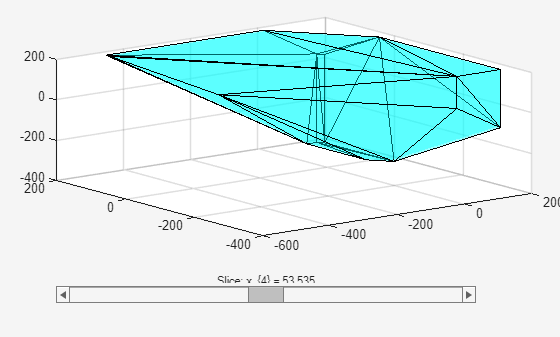

freeDim = 4;
visualizeSlice3D(Ac, bc, freeDim);

## Active set solver

H   = eye(4);
f   = -ie;
options = mpcActiveSetOptions;
[ie_proj, exitflag, iA, lambda] = mpcActiveSetSolver(H, f, Ac, bc, zeros(0, 4), zeros(0, 1), false(18, 1), options);
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

optimal_projection = struct();
optimal_projection.ie = ie_proj;
optimal_projection.iz = iz_proj;
optimal_projection.is = is_proj;
optimal_projection.ixy = ixy_proj;

% Max constraint violation original ie
max(Ac*ie - bc)

ans = 96.2113

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 2.8422e-14

## Hardnet-aff

ie_correction = pinvAc * max(0, Ac * ie - bc);
ie_proj = ie - ie_correction;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'HardNet-Aff')

Comparation of projection method: HardNet-Aff
  Original | Optimal | Actual
ie
  125.8895  125.8895  131.2345
  162.3168  114.2111  151.6266
 -149.2053 -149.2053 -143.8602
  165.3503  117.2447  154.6602
is
  201.3957  105.1844  190.7056
   67.0085   67.0085   56.3183
 -416.2113 -320.0000 -394.8310
 -278.3641 -230.2585 -273.0190
  282.3799  282.3799  287.7249
  186.5703  138.4646  175.8801
  -84.0912  -35.9856  -78.7462
  -70.5032  -70.5032  -65.1581
  111.8155   63.7099  101.1254
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 96.2113

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 74.8310

## Scalar clipping

Ac_ie = Ac * ie;
alpha_i = inf(size(Ac_ie));
pos = Ac_ie > 0;            
alpha_i(pos) = bc(pos) ./ Ac_ie(pos);
alpha = min(1, min(alpha_i));
ie_proj = alpha * ie;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Scalar Clipping')

Comparation of projection method: Scalar Clipping
  Original | Optimal | Actual
ie
  125.8895  125.8895   88.9251
  162.3168  114.2111  114.6565
 -149.2053 -149.2053 -105.3948
  165.3503  117.2447  116.7993
is
  201.3957  105.1844  112.0305
   67.0085   67.0085   60.1624
 -416.2113 -320.0000 -320.0000
 -278.3641 -230.2585 -193.7395
  282.3799  282.3799  245.4155
  186.5703  138.4646  138.9100
  -84.0912  -35.9856  -79.3506
  -70.5032  -70.5032  -26.6927
  111.8155   63.7099   63.2645
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 96.2113

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 2.8422e-14

## Cimmino original

Mean of constraint violations

K      = 5;         % Number of iterations
lambda = 1.5;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
n2 = sum(Ac.^2, 2); % Precalculate squared norm of each row of Ac
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0) ./ n2;
    d = (Ac.' * V) / size(Ac, 1);
    ie_proj = ie_proj - lambda * d;
end
toc

Elapsed time is 0.008326 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Mean')

Comparation of projection method: Cimmino Mean
  Original | Optimal | Actual
ie
  125.8895  125.8895  125.8895
  162.3168  114.2111  145.3464
 -149.2053 -149.2053 -149.2053
  165.3503  117.2447  148.3800
is
  201.3957  105.1844  167.4551
   67.0085   67.0085   67.0085
 -416.2113 -320.0000 -382.2707
 -278.3641 -230.2585 -261.3938
  282.3799  282.3799  282.3799
  186.5703  138.4646  169.5999
  -84.0912  -35.9856  -67.1209
  -70.5032  -70.5032  -70.5032
  111.8155   63.7099   94.8452
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 96.2113

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 62.2707

## Cimmino modified

Max of constraint violations

K      = 5;         % Number of iterations
lambda = 1;         % Relaxation factor
ie_proj = ie;       % Initialize projection
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0);
    [vmax, idx_max] = max(V);
    if vmax<=0
        break;
    end
    ai    = Ac(idx_max, :)';
    ri    = ai' * ie_proj - bc(idx_max);
    corr  = (ri / (ai' * ai)) * ai;
    ie_proj = ie_proj - lambda * corr;
end
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Max')

Comparation of projection method: Cimmino Max
  Original | Optimal | Actual
ie
  125.8895  125.8895  125.8895
  162.3168  114.2111  114.2111
 -149.2053 -149.2053 -149.2053
  165.3503  117.2447  117.2447
is
  201.3957  105.1844  105.1844
   67.0085   67.0085   67.0085
 -416.2113 -320.0000 -320.0000
 -278.3641 -230.2585 -230.2585
  282.3799  282.3799  282.3799
  186.5703  138.4646  138.4646
  -84.0912  -35.9856  -35.9856
  -70.5032  -70.5032  -70.5032
  111.8155   63.7099   63.7099
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 96.2113

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Dykstra

K        = 5;         % Número de iteraciones externas
lambda   = 1;       % Factor de relajación (p.ej. 1.2)
ie_proj  = ie;        % Inicializa la proyección
n2       = sum(Ac.^2, 2);    % Precalcula ||a_i||^2 para cada restricción
p        = zeros(size(Ac));  % Correcciones acumuladas, una fila por restricción

tic
for k = 1:K
    % Recorremos cada semiespacio i=1..m
    for i = 1:size(Ac,1)
        ai  = Ac(i,:).';
        bi  = bc(i);
        aux = ie_proj + p(i,:).';
        ri  = ai.'*aux - bi;
        if ri > 0
            corr   = (ri/n2(i)) * ai;
            x_new  = aux - lambda * corr;
        else
            x_new  = aux;
        end
        p(i,:)    = (aux - x_new).';
        ie_proj   = x_new;
    end
end
toc

Elapsed time is 0.008039 seconds.



iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Dykstra')

Comparation of projection method: Dykstra
  Original | Optimal | Actual
ie
  125.8895  125.8895  125.8895
  162.3168  114.2111  114.2111
 -149.2053 -149.2053 -149.2053
  165.3503  117.2447  117.2447
is
  201.3957  105.1844  105.1844
   67.0085   67.0085   67.0085
 -416.2113 -320.0000 -320.0000
 -278.3641 -230.2585 -230.2585
  282.3799  282.3799  282.3799
  186.5703  138.4646  138.4646
  -84.0912  -35.9856  -35.9856
  -70.5032  -70.5032  -70.5032
  111.8155   63.7099   63.7099
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 96.2113

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 2.8422e-14

## Douglas Peaceman Rachford

% inputs: Ac (m×n), bc (m×1), ie (n×1), K iteraciones
lambda = 1;               % relajación (normalmente 1)
x = ie;                   % estado
m = size(Ac,1);

tic
for k = 1:K
    x_old = x;
    % reflejar sucesivamente por cada semiespacio
    for i = 1:m
        ai = Ac(i,:).'; bi = bc(i);
        % proyección ortogonal a semiespacio i
        ri = ai.'*x - bi;
        if ri > 0
            p = x - (ri/(ai.'*ai)) * ai;
        else
            p = x;
        end
        % reflexión
        r = 2*p - x;
        % relajación
        x = x + lambda*(r - x);
    end
    % opcional: media con x_old para estabilidad DR
    x = 0.5*(x + x_old);
end
toc

Elapsed time is 0.007824 seconds.



ie_proj = x;
iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Dykstra')

Comparation of projection method: Dykstra
  Original | Optimal | Actual
ie
  125.8895  125.8895  125.8895
  162.3168  114.2111  114.2111
 -149.2053 -149.2053 -149.2053
  165.3503  117.2447  117.2447
is
  201.3957  105.1844  105.1844
   67.0085   67.0085   67.0085
 -416.2113 -320.0000 -320.0000
 -278.3641 -230.2585 -230.2585
  282.3799  282.3799  282.3799
  186.5703  138.4646  138.4646
  -84.0912  -35.9856  -35.9856
  -70.5032  -70.5032  -70.5032
  111.8155   63.7099   63.7099
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 96.2113

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0